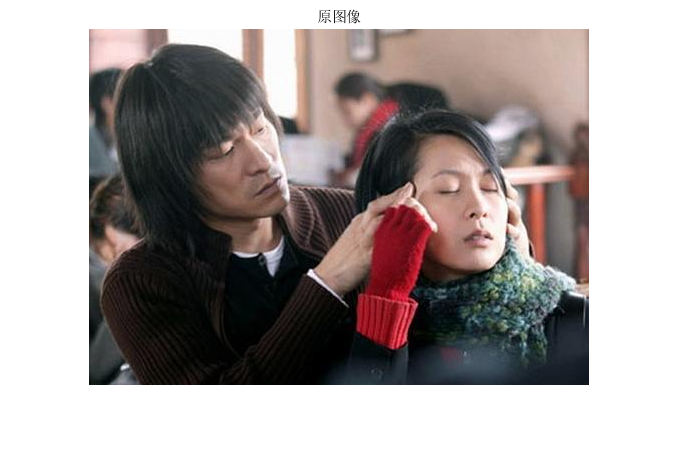

clc;
clear;
I=imread("08-刘德华.jpg");
I=im2double(I);
figure
imshow(I);
title("原图像");

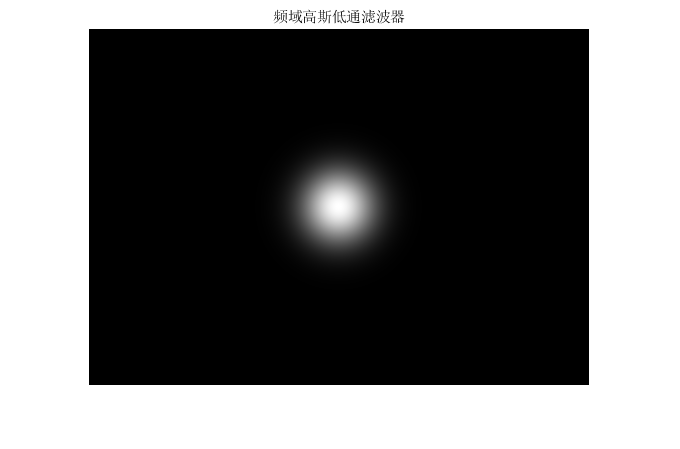

[row,col,~]=size(I);%获得图像的高度和宽度
H_gauss=zeros(row,col);
H_batt=zeros(row,col);
Y_guass=zeros(row,col,3);
Y_batt=zeros(row,col,3);
%对每个通道分别做傅里叶变换
Y=fftshift(fft2(I));
%图像中心点
M0=row/2;
N0=col/2;

%高斯低通滤波器的频域表示为：
%         H(u,v)=exp(-D(u,v)^2/(2*delta1^2))
%其中D(u,v)为(u，v)到中心点的距离,delta1为方差

delta1=25;     %设置方差
%求高斯低通滤波器
for x=1:row
    for y=1:col
        d2=(x-M0)^2+(y-N0)^2;  %计算点（x,y）到中心点的距离的平方
        H_gauss(x,y)=exp(-d2/(2*delta1^2)); %计算高斯低通滤波
    end
end
%绘制高斯低通滤波器
figure
imshow(H_gauss);
title("频域高斯低通滤波器");

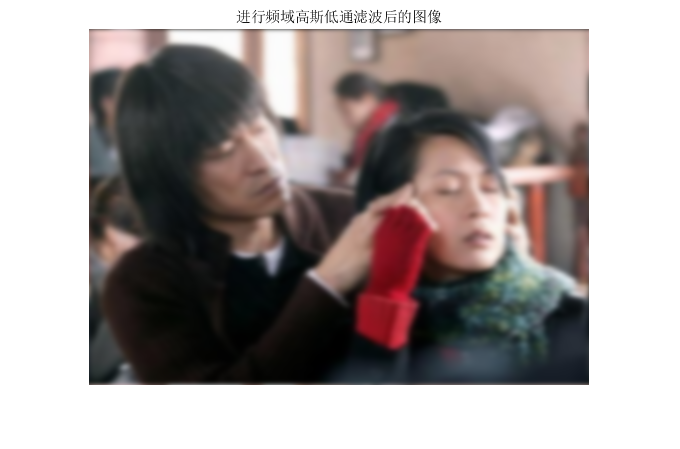

%对三个通道进行高斯低通滤波
for i=1:3
    Y_guass(:,:,i)=Y(:,:,i).*H_gauss;
end
%进行傅里叶反变换
I_guass=abs(ifft2(ifftshift(Y_guass)));
%绘制结果
figure
imshow(I_guass);
title('进行频域高斯低通滤波后的图像');

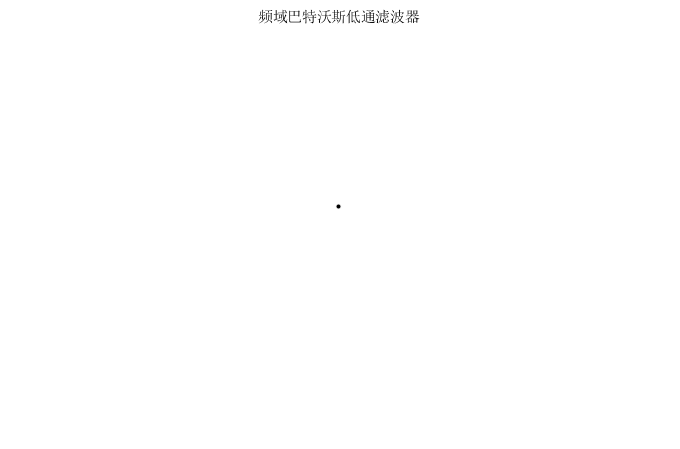

%n阶巴特沃斯高通滤波器的定义为：
%      H(u,v)=1/{1+[delta2/D(u，v)]^(2n)}
%其中D(u,v)为(u，v)到中心点的距离,delta为方差,n为阶数

delta2=2;%设置方差
n=5;%设置阶数

%求巴特沃斯低通滤波器
for x=1:row
    for y=1:col
        d2=sqrt((x-M0)^2+(y-N0)^2);  %计算点（x,y）到中心点的距离
        H_batt(x,y)=1/(1+(delta2/d2)^(2*n)); %计算巴特沃斯低通滤波器
    end
end
%绘制巴特沃斯低通滤波器
figure
imshow(H_batt);
title("频域巴特沃斯低通滤波器");

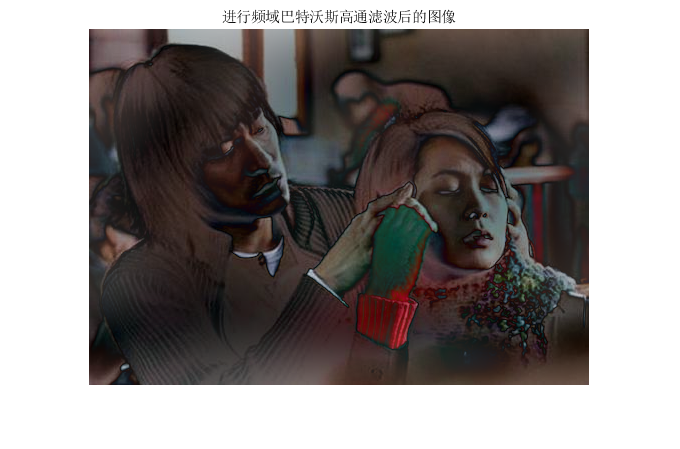

%对三个通道进行巴特沃斯低通滤波
for i=1:3
    Y_batt(:,:,i)=Y(:,:,i).*H_batt;
end
%进行傅里叶反变换
I_batt=abs(ifft2(ifftshift(Y_batt)));
%绘制结果
figure
imshow(I_batt);
title('进行频域巴特沃斯高通滤波后的图像');

%储存
imwrite(I_guass,'进行频域高斯低通滤波后的图像.jpg','jpg');
imwrite(I_batt,'进行频域巴特沃斯高通滤波后的图像.jpg','jpg');